Linearized Model for the inverted pendulum system:

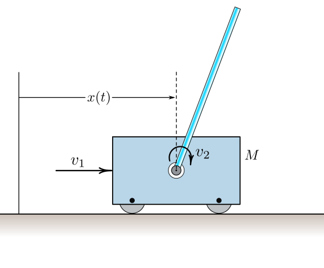

- Positive sense of $\theta$ is CW.

- Positive snese of $x$ is to the right.


$$state: \mathbf{x} = [x\ \dot{x}\ \theta\ \dot{\theta}]^T$$


% state = [x, xdot, theta, theta_dot]';

% A = [0,1,0,0;0,0,-(m*g)/M,0;0,0,0,1;0,0,(m+M)*g/(M*L),0];
% B = [0;1/M;0;-1/(M*L)];
% C = [1,0,0,0;0 0 1 0];
% D = [0;0];



$$\dot{\mathit{\mathbf{x}}} =\left(\begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & -\frac{g\,m}{M} & 0\\
0 & 0 & 0 & 1\\
0 & 0 & \frac{g\,\left(M+m\right)}{L\,M} & 0
\end{array}\right)\mathit{\mathbf{x}}+\left(\begin{array}{c}
0\\
\frac{1}{M}\\
0\\
-\frac{1}{L\,M}
\end{array}\right)\;\mathit{\mathbf{u}}\;$$



% if the positive sense of the pendulum angle is in the CCW direction, use 
% the following model
% A = [0,1,0,0;0,0,(m*g)/M,0;0,0,0,1;0,0,(m+M)*g/(M*L),0];
% B = [0;1/M;0;1/(M*L)];
% C = [1,0,0,0;0 0 1 0];
% D = [0;0];



$$\dot{\mathit{\mathbf{x}}} =\left(\begin{array}{cccc}
0 & 1 & 0 & 0\\
0 & 0 & \frac{g\,m}{M} & 0\\
0 & 0 & 0 & 1\\
0 & 0 & \frac{g\,\left(M+m\right)}{L\,M} & 0
\end{array}\right)\mathit{\mathbf{x}}+\left(\begin{array}{c}
0\\
\frac{1}{M}\\
0\\
\frac{1}{L\,M}
\end{array}\right)\;\mathit{\mathbf{u}}\;$$


% If the state is [x, theta, xdot, theta_dot], you can simply perform a
% state transformation by the matrix P = [1 0 0 0;0 0 1 0;0 1 0 0;0 0 0 1];
% that permutates the states in the state-vector.

syms m M l g real;
syms y t ydot tdot;
syms u1 u2;

q = [y;t];
qdot = [ydot; tdot];

% Mqddot + c = u
M = [m+M, m*l*cos(t);m*l*cos(t), m*l^2];
c = [-m*l*tdot^2*sin(t);-m*g*l*sin(t)];
u = [u1;u2];


$$state : \mathbf{x} =  [x\ \theta\ \dot{x}\ \dot{\theta}]^T$$
  


$$\dot{\mathbf{x}} =\mathbf{f}(\mathbf{x, \mathbf{u}})$$


x = [q;qdot];
f = simplify([qdot; inv(M)*(u-c)], 'Steps', 3);

input-affine form of non-linear equations:


$$\dot{\mathbf{x}} = \hat{\mathbf{f}}(\mathbf{x}) + G(\mathbf{x})\mathbf{u}$$


G = simplify(jacobian(f, u), 'Steps', 3);
fhat = simplify(f - G*u, 'Steps', 5);

% -------------
% f2 uses the state vector x2
x2 = [y;ydot;t;tdot];
P = [1 0 0 0;0 0 1 0;0 1 0 0;0 0 0 1];
f2 = P*f;
G2 = simplify(jacobian(f2, u));
fhat2 = simplify(f2 - G2*u, 'Steps', 5);


$$state = [x\ \theta\ \dot{x}\ \dot{\theta}]^T$$
  

% state: x: Linearize around the equilibrium point
A = simplify(subs(simplify(jacobian(f, x)), [y, ydot, t, tdot], [0, 0, 0, 0])) 

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & -\frac{g\,m}{M} & 0 & 0\\ 0 & \frac{g\,\left(M+m\right)}{M\,l} & 0 & 0 \end{array}\right)$$

B = simplify(subs(simplify(jacobian(f, u)), [y, ydot, t, tdot], [0, 0, 0, 0]))

$$B = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ \frac{1}{M} & -\frac{1}{M\,l}\\ -\frac{1}{M\,l} & \frac{M+m}{M\,l^{2}\,m} \end{array}\right)$$


$$state = [x\ \dot{x}\ \theta\ \dot{\theta}]^T$$


% state: x2: Linearize around the equilibrium point
A2 = simplify(subs(simplify(jacobian(f2, x2)), [y, ydot, t, tdot], [0, 0, 0, 0])) 

$$A2 = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,m}{M} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{g\,\left(M+m\right)}{M\,l} & 0 \end{array}\right)$$

B2 = simplify(subs(simplify(jacobian(f2, u)), [y, ydot, t, tdot], [0, 0, 0, 0]))

$$B2 = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{M} & -\frac{1}{M\,l}\\ 0 & 0\\ -\frac{1}{M\,l} & \frac{M+m}{M\,l^{2}\,m} \end{array}\right)$$